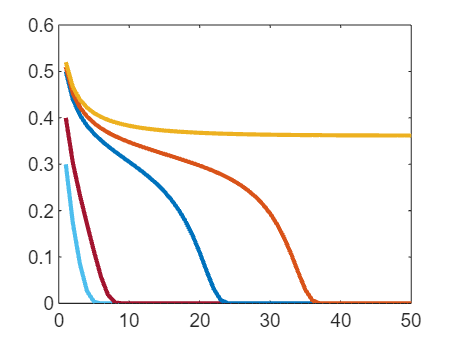

dc = 5;
dv = 3;
powery = dc-1;
ps = [0.3, 0.4, 0.5, 0.51, 0.52];
no_of_it = 1:1:50;


for p = ps

     p_analytical = zeros(1,length(no_of_it));
     p_analytical(1)=p;
     for it = 1:1:max_it-1
         p_analytical(it+1) = p*power((1-power((1-p_analytical(it)), dc-1)),dv-1);
     end
     plot(no_of_it,p_analytical,'DisplayName',sprintf('Analytical p=%.2f',p),LineWidth=2);
     hold on;      
    
end